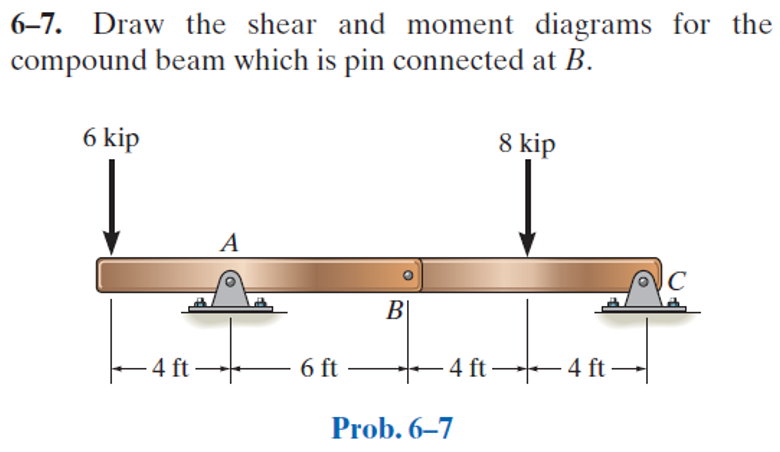

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-7P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-7P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('concentrated', 'force', -6*u.kip, 0);
b = b.add('reaction', 'force', 'Ra', 4*u.ft);
b = b.add('hinge', 'force', 'Hb', 10*u.ft);
b = b.add('concentrated', 'force', -8*u.kip, 14*u.ft);
b = b.add('reaction', 'force', 'Rc', 18*u.ft);
b.L = 18*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\left(x-4\,\mathrm{ft}\right)\,\left(3\,x^{2}+12\,x\,\mathrm{ft}+496\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 4\,\mathrm{ft}\\ -\frac{2\,\left(x-4\,\mathrm{ft}\right)\,\left(-x^{2}+26\,x\,\mathrm{ft}+208\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},10\,\mathrm{ft}\right]\\ \frac{2\,\left(x^{3}-30\,x^{2}\,\mathrm{ft}+528\,x\,{\mathrm{ft}}^{2}-5488\,{\mathrm{ft}}^{3}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(10\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{2\,x\,\left(x-18\,\mathrm{ft}\right)\,\left(x-36\,\mathrm{ft}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{9\,x^{2}+448\,{\mathrm{ft}}^{2}}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 4\,\mathrm{ft}\\ -\frac{2\,\left(-3\,x^{2}+60\,x\,\mathrm{ft}+104\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},10\,\mathrm{ft}\right]\\ \frac{2\,\left(x^{2}-20\,x\,\mathrm{ft}+176\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(10\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{2\,\left(x^{2}-36\,x\,\mathrm{ft}+216\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -6\,x\,\mathrm{kip} & \text{ if }x\leq 4\,\mathrm{ft}\\ 4\,\left(x-10\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -4\,\left(x-18\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -6\,\mathrm{kip} & \text{ if }x\leq 4\,\mathrm{ft}\\ 4\,\mathrm{kip} & \text{ if }x\in \left(4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -4\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 10\,\mathrm{kip}\\ \mathrm{Rc} & 4\,\mathrm{kip} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & -4\,\mathrm{kip} \end{array}\right)$$

# shear and moment diagram

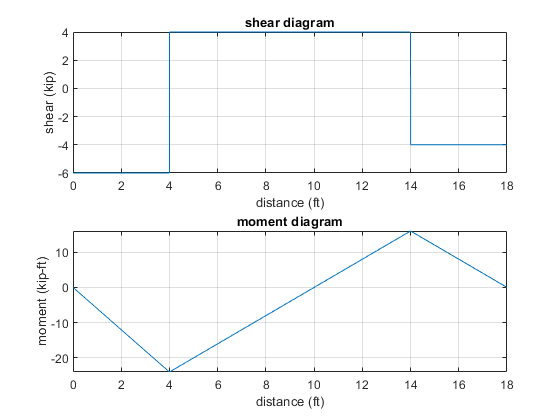

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;